## นายพิชญ์ รังษีจำรัส 62070502215    Homework 03 :

Bring up Source Image and Gray scaled it

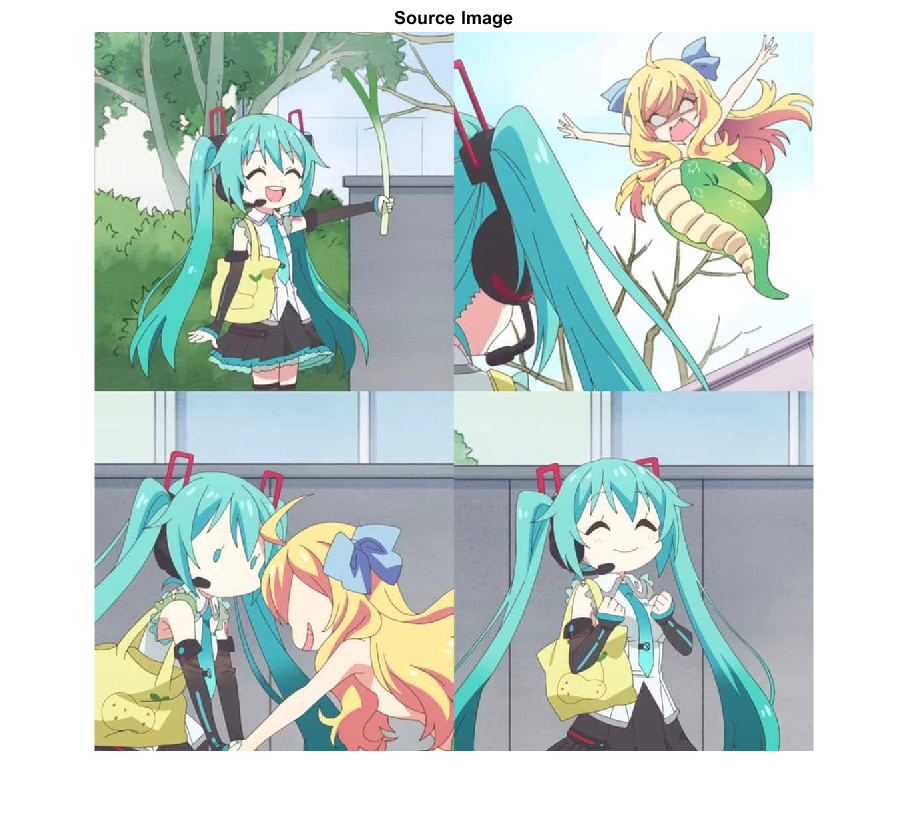

clear
clc
% input image from source
I = imread('FB_IMG_1657386868546.jpg');
imshow(I)
title("Source Image")

% Convert rgb image to grayscale image
r = I(:,:,1);
g = I(:,:,2);
b = I(:,:,3);
I2 = (0.3*r) + (0.6*g) + (0.1*b)

I2 = 1080×1080 uint8 matrix
   185   185   173   153   147   150   136   115   116   131   143   137   126   127   147   169   172   176   173   166   168   183   192   192   179   182   184   186   183   182   180   178   183   183   183   181   181   180   180   180   181   180   180   178   177   175   174   173   146   138
   171   167   155   141   133   130   121   110   115   130   143   143   133   133   143   155   149   154   153   148   155   173   185   185   179   182   184   186   183   182   180   178   183   183   181   181   180   180   180   180   181   180   180   178   177   175   174   173   171   165
   155   144   132   127   122   113   110   110   125   135   145   150   145   142   143   145   135   139   140   137   145   165   179   180   179   182   184   186   183   182   180   178   181   181   181   180   180   180   180   180   181   180   180   178   177   175   174   173   186   185
   148   127   114   118   123   117   117   125   140   145   148   

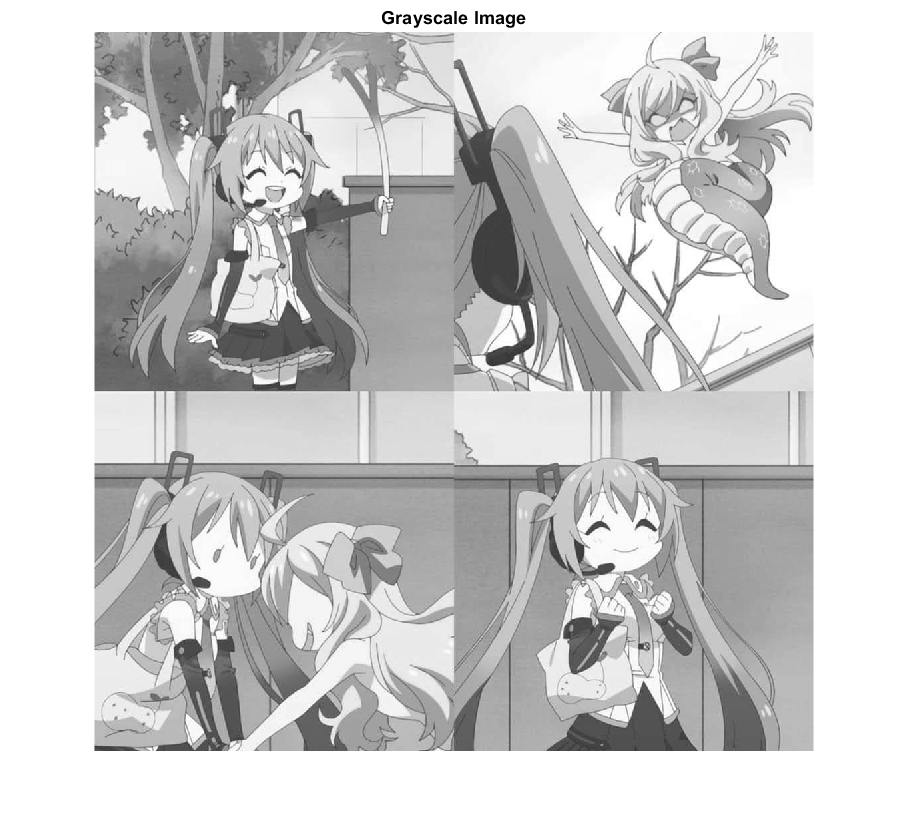

% Grayscale Image Result
imshow(I2)
title("Grayscale Image")

% Get image's resolution
[x y] = size(I2)

x = 1080

y = 1080

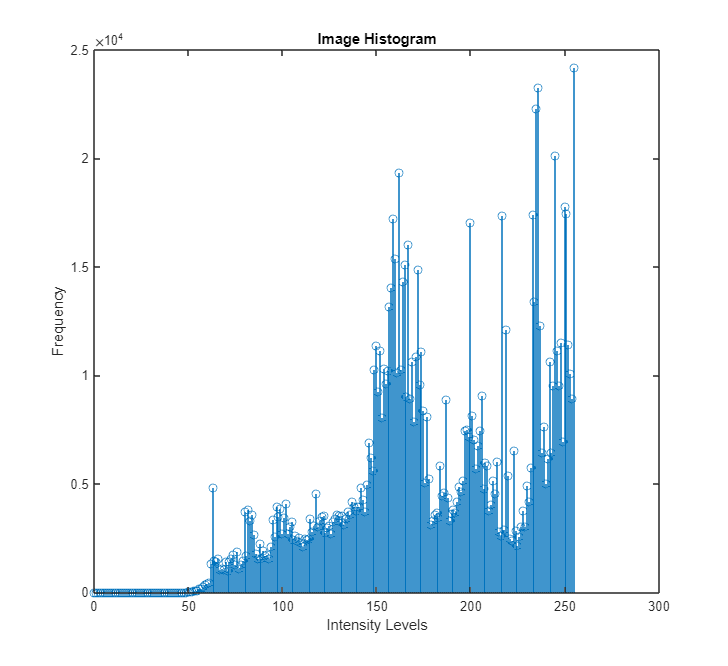

% Plot image histogram
population = zeros(1,256);
for i = 1:x
    for j = 1:y
        for k = 0:255
            if k == I2(i,j)
                population(k+1) = population(k+1) + 1 ;
            end
        end
    end
end
% Histogram Result
stem(0:255,population)
title("Image Histogram")
xlabel("Intensity Levels")
ylabel("Frequency")

Write a program for histogram equalization.

%find Probability Density Function (pdf)
population

population =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     2     1     3     3     4     6     4     7    11     9


population2 = population(:,:)/(x*y)

population2 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000         0         0         0    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


cdf = zeros(1,256);
%sum(population2(:,:))
%find Cumulative Distribution Function (cdf)
for k = 1:256
    for o = 1 :256
        cdf(:,o) = sum(population2(:,1:o));
    end
end
cdf

cdf =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


%map value to 0-255 intensity value
cdfnew = cdf(:,:)*255

cdfnew =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0002    0.0002    0.0002    0.0002    0.0004    0.0004    0.0009    0.0011    0.0017    0.0024    0.0033    0.0046    0.0055    0.0070    0.0094    0.0114


I3 = zeros(x,y);
%assign intensity to the pixel
for i = 1:x
    for j = 1:y
        for k = 0:255
            if k == I2(i,j)
                I3(i,j) = cdfnew(:,k+1);
            end
        end
    end
end
I3 = uint8(I3)

I3 = 1080×1080 uint8 matrix
   135   135   120    66    54    60    43    28    28    39    49    44    35    36    54   111   118   126   120   103   108   132   142   142   129   132   134   136   132   132   130   129   132   132   132   131   131   130   130   130   131   130   130   129   127   125   123   120    53    45
   115   107    71    47    41    38    32    25    28    38    49    49    41    41    49    71    58    69    66    55    71   120   135   135   129   132   134   136   132   132   130   129   132   132   131   131   130   130   130   130   131   130   130   129   127   125   123   120   115   101
    71    50    40    36    33    26    25    25    35    42    51    60    51    48    49    51    42    46    46    44    51   101   129   130   129   132   134   136   132   132   130   129   131   131   131   130   130   130   130   130   131   130   130   129   127   125   123   120   136   135
    55    36    27    30    34    29    29    35    46    51    55   

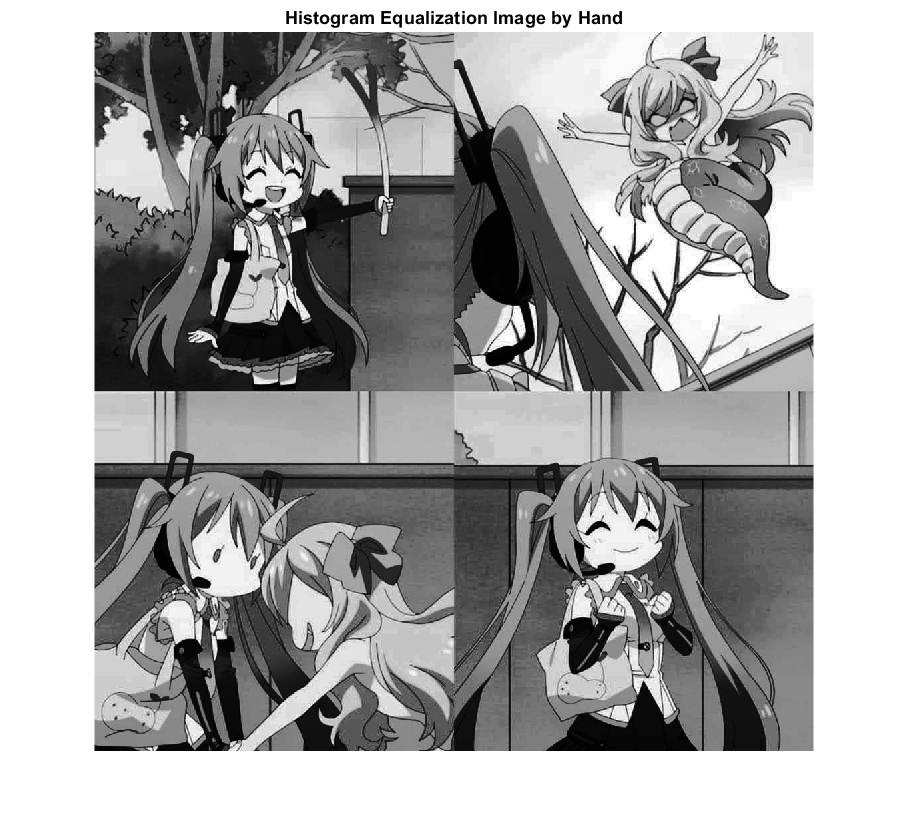

imshow(I3)
title("Histogram Equalization Image by Hand")

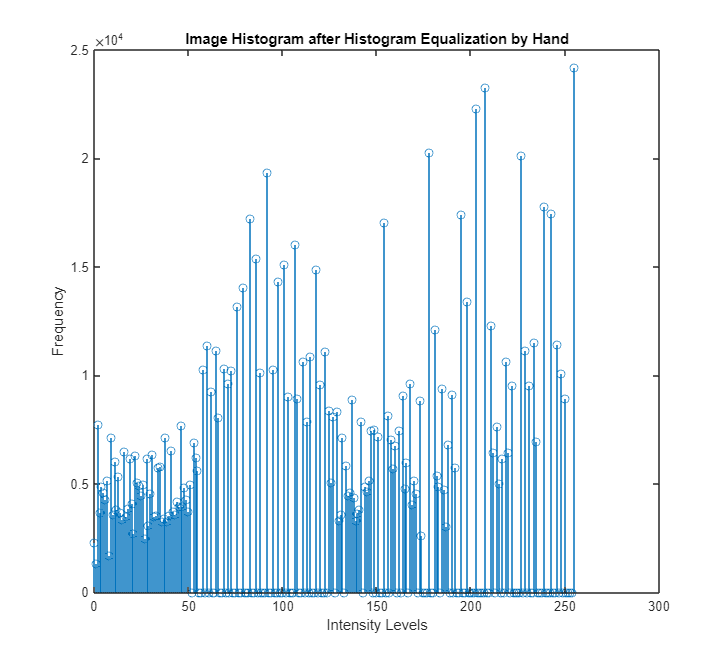

% Plot image histogram after Histogram Equalization
population3 = zeros(1,256);
for i = 1:x
    for j = 1:y
        for k = 0:255
            if k == I3(i,j)
                population3(k+1) = population3(k+1) + 1 ;
            end
        end
    end
end
% Histogram Result
stem(0:255,population3)
title("Image Histogram after Histogram Equalization by Hand")
xlabel("Intensity Levels")
ylabel("Frequency")

%find Histogram Equalization Image by Function
I4 = histeq(I2)

I4 = 1080×1080 uint8 matrix
   134   134   117    65    53    57    40    24    28    36    49    40    32    32    53   109   117   125   117   101   105   134   142   142   130   130   134   134   134   130   130   130   134   134   134   130   130   130   130   130   130   130   130   130   125   125   121   117    53    45
   113   105    69    45    40    36    28    24    24    36    49    49    40    40    49    69    57    65    65    53    69   117   134   134   130   130   134   134   134   130   130   130   134   134   130   130   130   130   130   130   130   130   130   130   125   125   121   117   113    97
    69    49    36    32    32    24    24    24    32    40    49    57    49    49    49    49    40    45    45    40    49    97   130   130   130   130   134   134   134   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   125   125   121   117   134   134
    53    32    24    28    32    28    28    32    45    49    53   

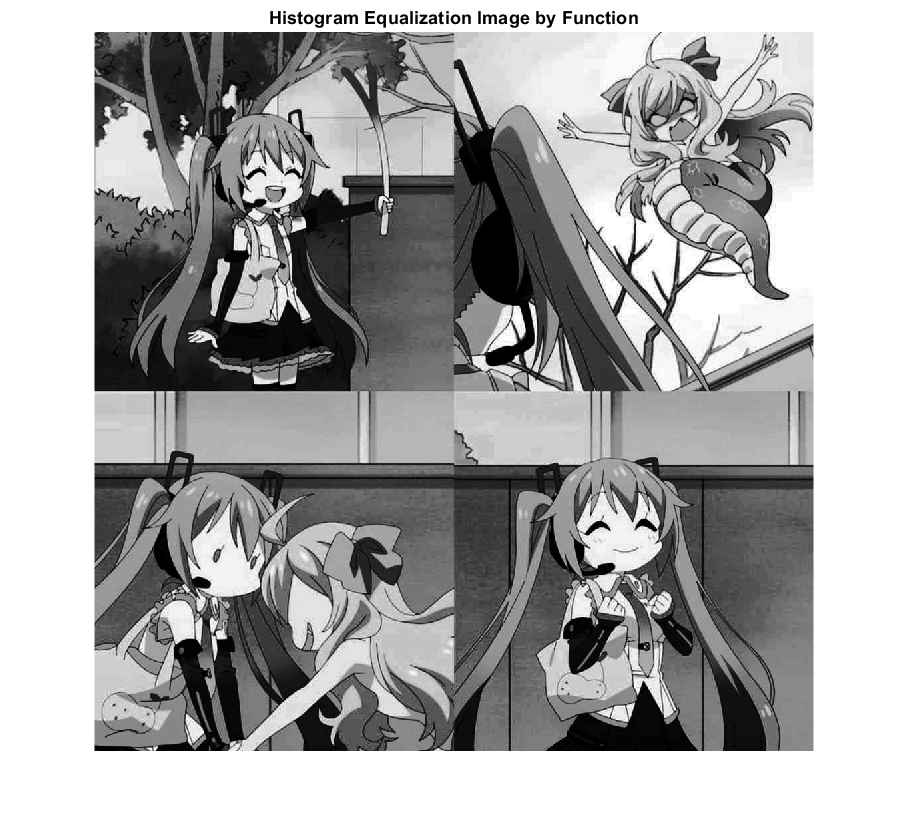

imshow(I4)
title("Histogram Equalization Image by Function")

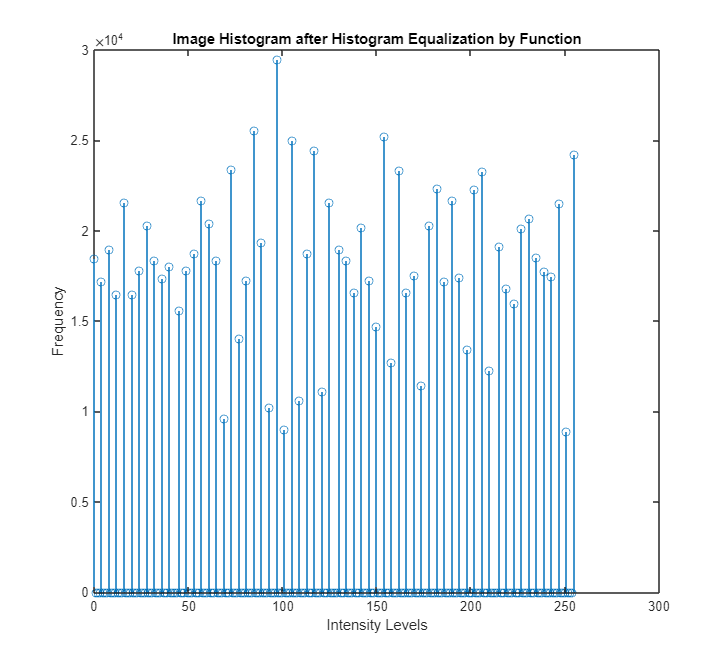

% Plot image histogram after Histogram Equalization by Function
population4 = zeros(1,256);
for i = 1:x
    for j = 1:y
        for k = 0:255
            if k == I4(i,j)
                population4(k+1) = population4(k+1) + 1 ;
            end
        end
    end
end
% Histogram Result
stem(0:255,population4)
title("Image Histogram after Histogram Equalization by Function")
xlabel("Intensity Levels")
ylabel("Frequency")